## Zadanie 2

clear all; close all;
[img, cmap] = imread("lena512.png");  

Utworzenie filtru dolno i górno przepustowego i wyświetlenie ich

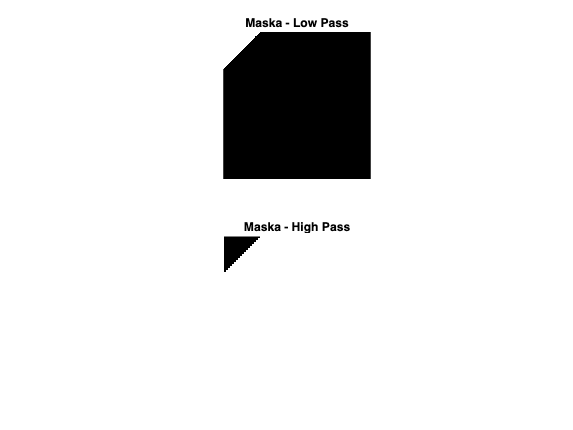

[M, N, ~] = size(img);

K = 128;
H_LOW_PASS = myTriangleMask(M, N, K);

K = 128;
H_HIGH_PASS = ones(M, N) - myTriangleMask(M, N, K);

figure;
subplot(2,1,1); imshow(H_LOW_PASS); title("Maska - Low Pass");
subplot(2,1,2); imshow(H_HIGH_PASS); title("Maska - High Pass");

Obliczanie odpowiedzi impulsowych filtrów

N = 32;
window = blackman(32);
h_low_pass = abs(fwind1(H_LOW_PASS, window));
h_high_pass = abs(fwind1(H_HIGH_PASS, window));

Przekształcenie filtru do dziedziny częstotliwości

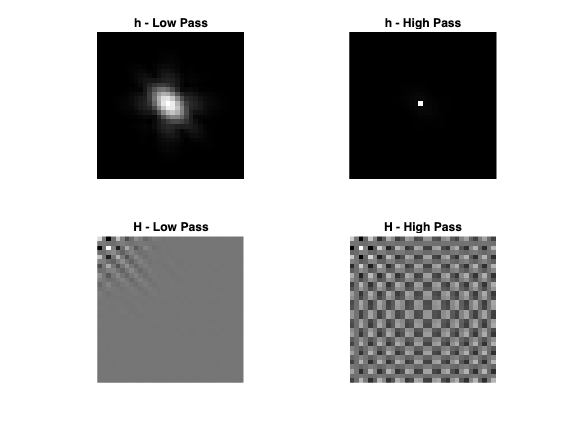

H_LOW_PASS = dct2(h_low_pass);
H_HIGH_PASS = dct2(h_high_pass);

figure;
subplot(2,2,1); imshow(h_low_pass, cmap); title("h - Low Pass");
subplot(2,2,2); imshow(h_high_pass, cmap); title("h - High Pass");
subplot(2,2,3); imshow(H_LOW_PASS, cmap); title("H - Low Pass"); % frequency
subplot(2,2,4); imshow(H_HIGH_PASS, cmap); title("H - High Pass"); % frequency

Filtracja obrazu za pomocą odpowiedzi impulsowych

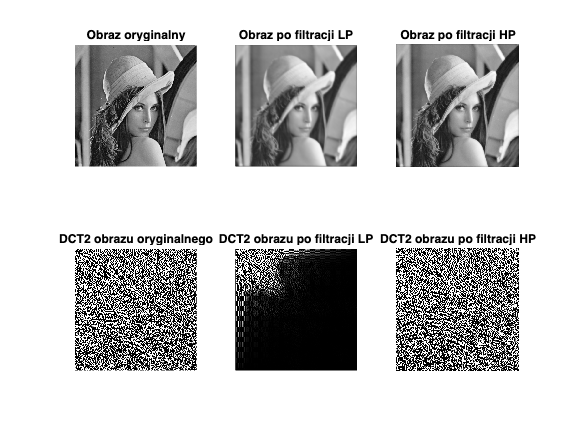

img_low_pass  = filter2(h_low_pass, img);
img_high_pass = filter2(h_high_pass, img);

% przeniesienie obrazu do dziedziny częstotliwości
IMG_LOW_PASS  = dct2(img_low_pass);
IMG_HIGH_PASS = dct2(img_high_pass);
IMG = dct2(img);

figure;
subplot(2,3,1); imshow(img, cmap); title("Obraz oryginalny");
subplot(2,3,2); imshow(img_low_pass, cmap); title("Obraz po filtracji LP");
subplot(2,3,3); imshow(img_high_pass, cmap); title("Obraz po filtracji HP");
subplot(2,3,4); imshow(IMG); title("DCT2 obrazu oryginalnego");
subplot(2,3,5); imshow(IMG_LOW_PASS); title("DCT2 obrazu po filtracji LP");   
subplot(2,3,6); imshow(IMG_HIGH_PASS); title("DCT2 obrazu po filtracji HP");

Filtracja Gaussowska

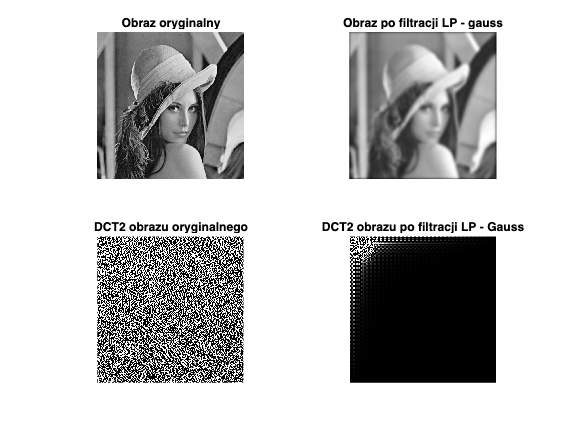

hsize = 32;
sigma = 5;
h = fspecial('gaussian', hsize, sigma);

img_gauss = filter2(h, img);
IMG_GAUSS = dct2(img_gauss);

figure;
subplot(221); imshow(img, cmap); title("Obraz oryginalny");
subplot(222); imshow(img_gauss, cmap); title("Obraz po filtracji LP - gauss");
subplot(223); imshow(IMG); title("DCT2 obrazu oryginalnego");
subplot(224); imshow(IMG_GAUSS); title("DCT2 obrazu po filtracji LP - Gauss");